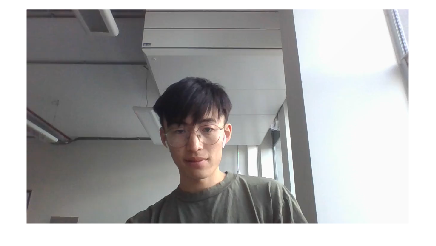

vid = VideoReader('myface.avi');

frame = vid.readFrame();
figure
imshow(frame)

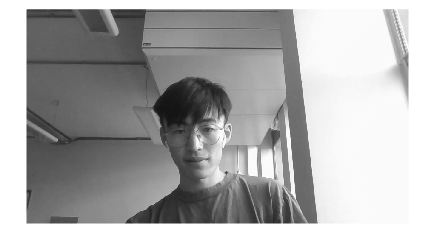


y_frame = rgb2y(frame);

% Normalize y_frame to be between 0 and 1
y_frame_normalized = y_frame / 255;
figure
imshow(y_frame_normalized)

% sample the video
vid.CurrentTime = 0;
idx = 1;

% set number of frames to extract
n_frames = 100;
height = size(frame, 1);
length = size(frame, 2);
% vidcube = zeros(height, length, n_frames);
vidcube = zeros(n_frames, height, length);

% dump video frames into a datacube
while vid.hasFrame() && idx <= n_frames
    temp_frame = vid.readFrame();
    y_temp_frame = rgb2y(temp_frame);
    y_temp_frame_norm = y_temp_frame / 255;
    % vidcube(idx, :, :, :) = temp_frame;

    % create video datacube (3d array)
    vidcube(:,idx,:) = y_temp_frame_norm;
    idx = idx + 1;
end



size(vidcube)

ans =          100         720        1280


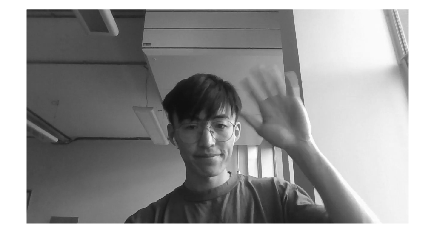

figure
imshow(squeeze(vidcube(:, 35,:)));

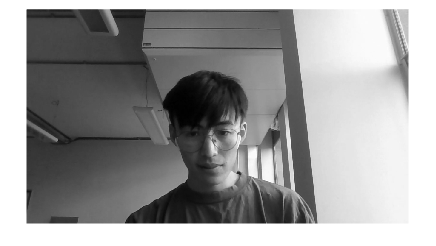

Index in position 1 exceeds array bounds. Index must not exceed 100.

% play the video from the vidcube array data

numFrames = size(vidcube, 3);

frameRate = 30; % Adjust based on the original video's frame rate
pauseDuration = 1 / frameRate;

% Loop through each frame in the vidcube and display it
for idx = 1:numFrames-1
    % Display the current frame using imshow
    imshow(squeeze(vidcube(idx, :,:)), []);
    
    % Pause to simulate video playback frame rate
    pause(pauseDuration);
end

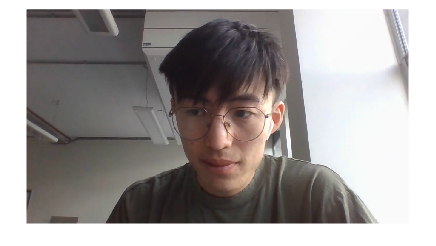

vid.currentTime = 0;

while vid.hasFrame()
    temp = vid.readFrame();
    imshow(temp);
    pause(1.0/vid.FrameRate) ;
end

function Y = rgb2y(RGB)
    % Transformation matrix to get Y component
    transformMat = [0.299, 0.587, 0.114];
    % Apply the matrix to each pixel
    Y = double(RGB(:,:,1)) * transformMat(1) + double(RGB(:,:,2)) * transformMat(2) + double(RGB(:,:,3)) * transformMat(3);
end